Looks at the distribution of mins for different clean parameters

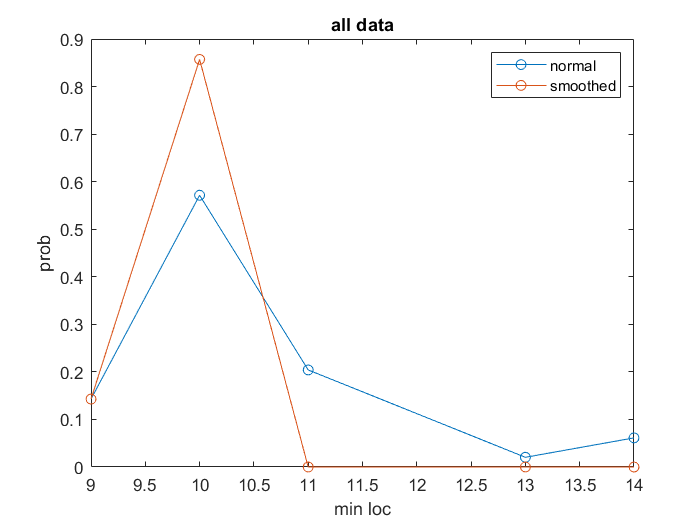

% looks at overall distribution

all_data = load("2_65kb_fluo3DN_04_24_21.mat");
all_data = all_data.all_data;
all_data = all_data([all_data.num_traces] > 100);

type = 'r1_min3';

all_mins = [all_data.(type)];
all_mins_s = [all_data.([type '_s'])];

all_poss = unique([all_mins all_mins_s]);
nums = zeros(1, length(all_poss));
nums_s = zeros(1, length(all_poss));
for i = 1:length(all_poss)
    nums(i) = length(find(all_mins == all_poss(i))) / length(all_mins);
    nums_s(i) = length(find(all_mins_s == all_poss(i))) / length(all_mins_s); 
end

figure();
plot(all_poss, nums, 'o-');
hold on
plot(all_poss, nums_s, 'o-');
xlabel('min loc');
ylabel('prob')
title('all data')
legend('normal', 'smoothed')

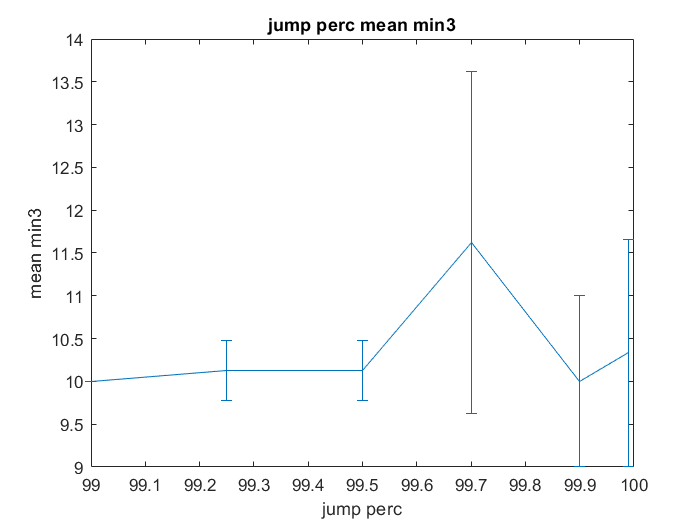


% looks at mean/sd value across jump percentages
jumps = sort(unique([all_data.jump_perc]));
means = [];
sds = [];
for jump = jumps
    some_data = all_data([all_data.jump_perc] == jump);
    means = [means mean([some_data.(type)])];
    sds = [sds std([some_data.(type)])];
end
figure();
errorbar(jumps, means, sds);
xlabel('jump perc')
ylabel('mean min3');
title('jump perc mean min3')

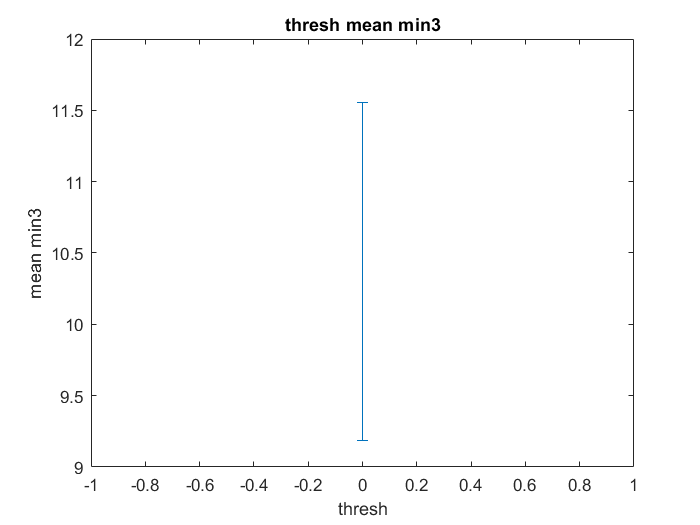


% looks at mean/sd value across thresh
threshes = sort(unique([all_data.thresh]));
means = [];
sds = [];
for thresh= threshes
    some_data = all_data([all_data.thresh] == thresh);
    means = [means mean([some_data.(type)])];
    sds = [sds std([some_data.(type)])];
end
figure();
errorbar(threshes, means, sds);
xlabel('thresh')
ylabel('mean min3');
title('thresh mean min3')

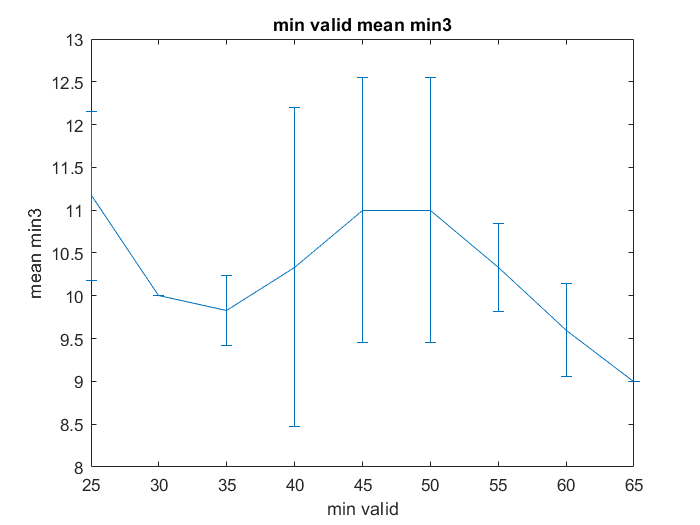


% looks at mean/sd value across min_valids
% looks at mean/sd value across thresh
min_valids = sort(unique([all_data.min_valid]));
means = [];
sds = [];
for min_valid= min_valids
    some_data = all_data([all_data.min_valid] == min_valid);
    means = [means mean([some_data.(type)])];
    sds = [sds std([some_data.(type)])];
end
figure();
errorbar(min_valids, means, sds);
xlabel('min valid')
ylabel('mean min3');
title('min valid mean min3')

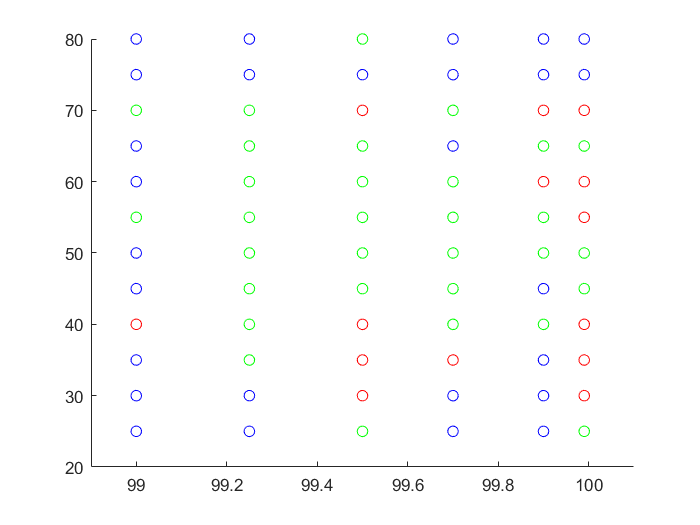

% makes scatter plot where each color is a different estimate

all_data = load("1_9kb_fluo3DN_04_24_21.mat");
all_data = all_data.all_data;
type = 'r1_min3';
target_val = 8;

figure();
for idx = 1:length(all_data)
    if all_data(idx).(type) == target_val
        my_color = 'blue';
    elseif all_data(idx).(type) > target_val
        my_color = 'green';
    else
        my_color = 'red';
    end
    scatter(all_data(idx).jump_perc, all_data(idx).min_valid,40, ...
        my_color);    
    %scatter(all_data(idx).jump_perc, all_data(idx).min_valid,40, ...
    %    all_data(idx).r4_min3);
    hold on
end
xlim([98.9,100.1])